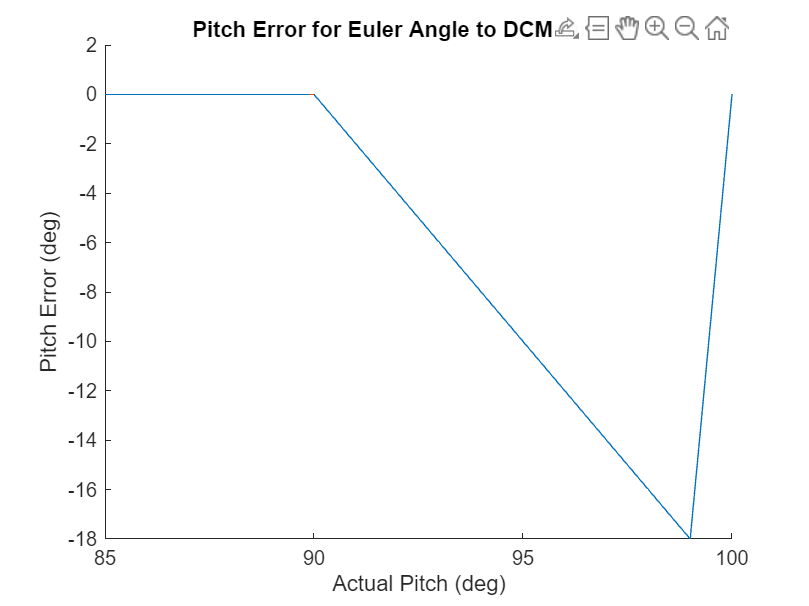

maxpitch = 100; %deg
pitch = 0:1:maxpitch; %x-value vector for plot

%Reserve memory for y-axis vector
pitcherror = zeros(length(pitch),1);

%iterate and populate pitcherror
for i = 1:(maxpitch)
    [phi, theta, psi] = dcm2euler(euler2dcm(1, pitch(i), 1));
    pitcherror(i,1) = theta - pitch(i);
end

%plot pitcherror
figure
hold on
plot(pitch, pitcherror)
title("Pitch Error for Euler Angle to DCM function")
xlabel("Actual Pitch (deg)")
ylabel("Pitch Error (deg)")
xlim([85 100])